The data is loaded and then plotted as a sanity check.

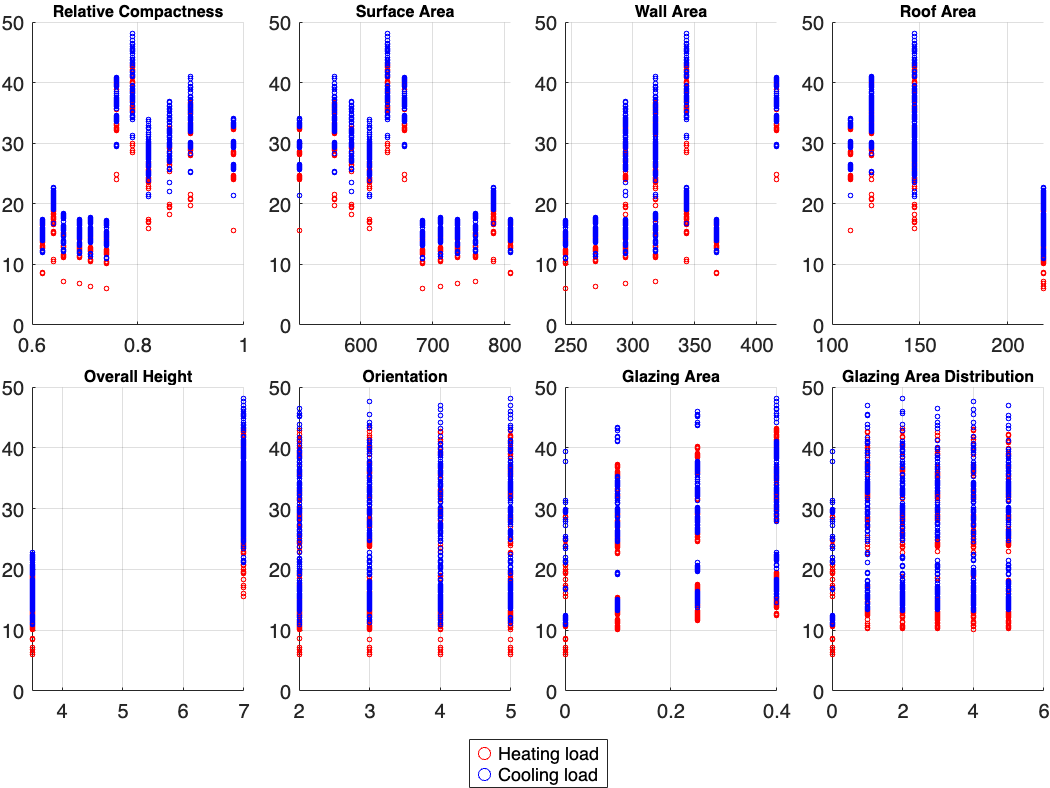

data = readtable("../Data/ENB2012_data.xlsx");

Headers = [
    "Relative Compactness"
    "Surface Area"
    "Wall Area"
    "Roof Area"
    "Overall Height"
    "Orientation"
    "Glazing Area"
    "Glazing Area Distribution"
    "Heating Load"
    "Cooling Load"];

data.Properties.VariableNames = Headers;
M = table2array(data);

figure()
t = tiledlayout(2, 4, "TileSpacing", "compact", "Padding", "none");

for i = 1:8
    ax = nexttile;
    
    h1 = scatter(M(:,i), M(:,9), "r", SizeData=5);
    hold on
    h2 = scatter(M(:,i), M(:,10), "b", SizeData=5);
    
    title(Headers(i),FontSize=8)
    grid on
    hold off
end

lgd = legend([h1 h2], "Heating load", "Cooling load");
lgd.Layout.Tile = "south";

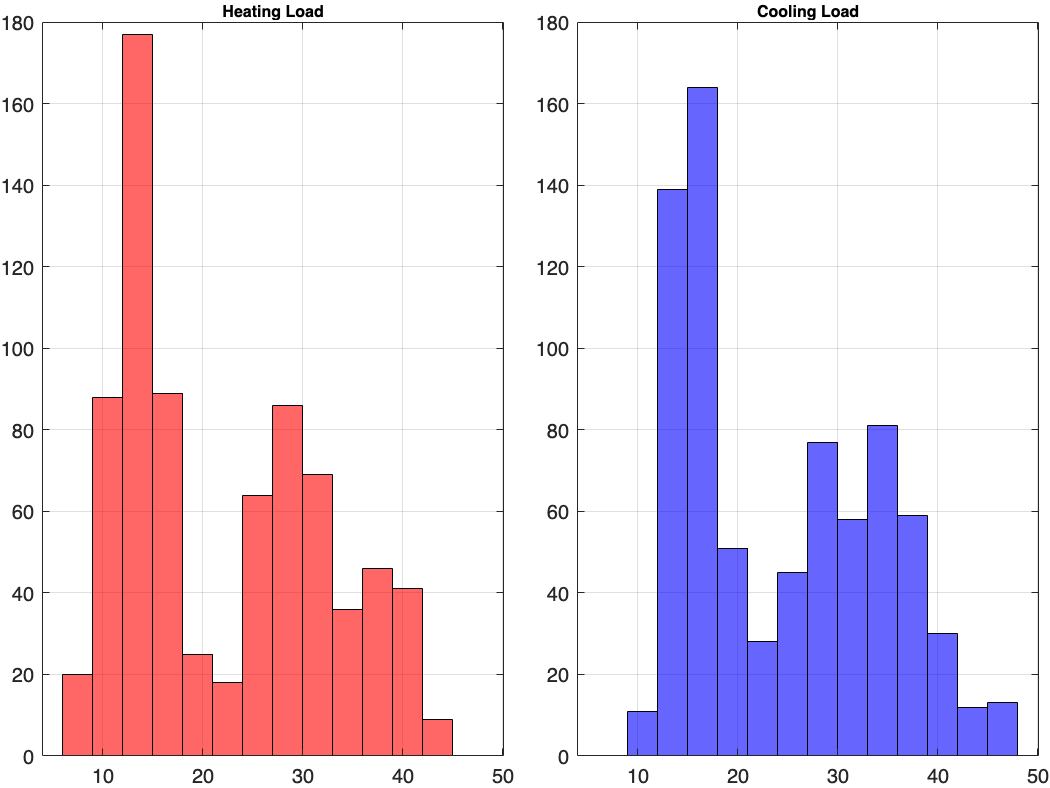


figure()
t = tiledlayout(1, 2, "TileSpacing", "compact", "Padding", "none");

edges = linspace(min([M(:,9); M(:,10)]), max([M(:,9); M(:,10)]), 15);

ax1 = nexttile;
histogram(M(:,9), edges, "FaceColor", "r");
title("Heating Load", FontSize=8)
grid on

ax2 = nexttile;
histogram(M(:,10), edges, "FaceColor", "b");
title("Cooling Load", FontSize=8)
grid on

The normal equations can be found, and linear regression can be algebraically solved using inverse matrices, to apply linear regression on the heating load. However, MatLab warns about the matrix being ill conditioned, which can cause numerical stability problems.

X = [ones(size(M,1),1), M(:,1:8)];

y = M(:,9);
beta = (X' * X) \ X' * y;


RMSE = sqrt(1/length(y) * sum((y - X * beta).^2))

RMSE = 3.0050

If the QR factorization of X is taken instead, the same problem is found

[Q,R] = qr(X);
beta = R \ Q'* y;


RMSE = sqrt(1/length(y) * sum((y - X * beta).^2))

RMSE = 2.9190


disp("Intercept:")

Intercept:


disp(beta(1))

   84.0134



disp("Coefficients:")

Coefficients:


disp(beta(2:end))

  -64.7734
   -0.0873
    0.0608
         0
    4.1700
   -0.0233
   19.9327
    0.2038


The rank defficiency warned by Matlab suggest linear dependency between the parameters, which makes the method numerically stable. Therefore, it seems plausible that reducing the number of features will improve the numerical stability of this linear regression. Also, it can be noted how the coefficient for feature 4 is exactly 0 (or at least below machine precission). This suggests this feature might be strongly correlated with some others.

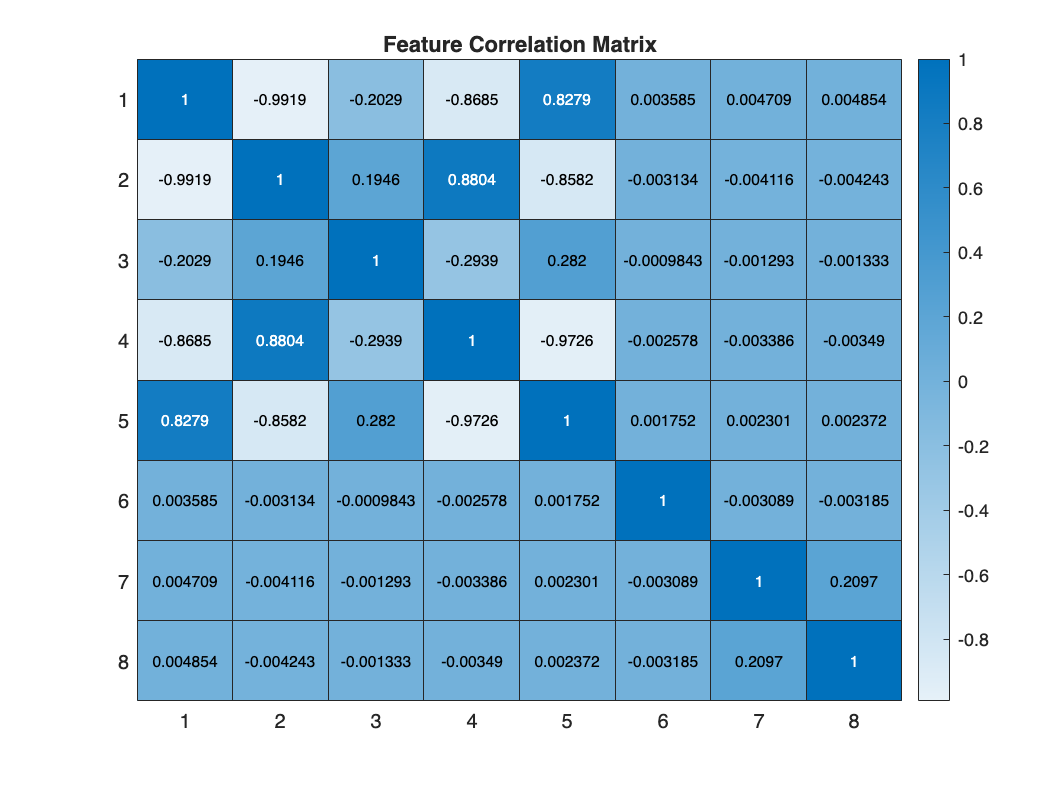

R = corrcoef(X(2:end,2:end));

figure()
heatmap(R);
title('Feature Correlation Matrix');


Xz = zscore(X(2:end,2:end));
[~, p] = size(Xz);

[U,S,V] = svd(Xz, 'econ');

dependency = V(:,end);

disp(table((1:p)', dependency, ...
    'VariableNames', {'Feature','Coefficient'}));

    Feature    Coefficient
    _______    ___________
       1       -1.0494e-15
       2           0.65948
       3          -0.32724
       4          -0.67675
       5        2.2686e-16
       6       -1.6773e-16
       7        4.3057e-17
       8        1.0002e-16


It can be seen how feature 4 is strongly related with feature 2. Therefore, removing feature 4 might improve the fit.

disp('Feature 4 removed')

Feature 4 removed


X_reduced = X;
X_reduced(:,5) = [];

beta = (X_reduced' * X_reduced) \ X_reduced' * y;

RMSE = sqrt(1/length(y) * sum((y - X_reduced * beta).^2))

RMSE = 2.9190

It can be seen that RMSE is unchanged, but numerical stability problems have been avoided.

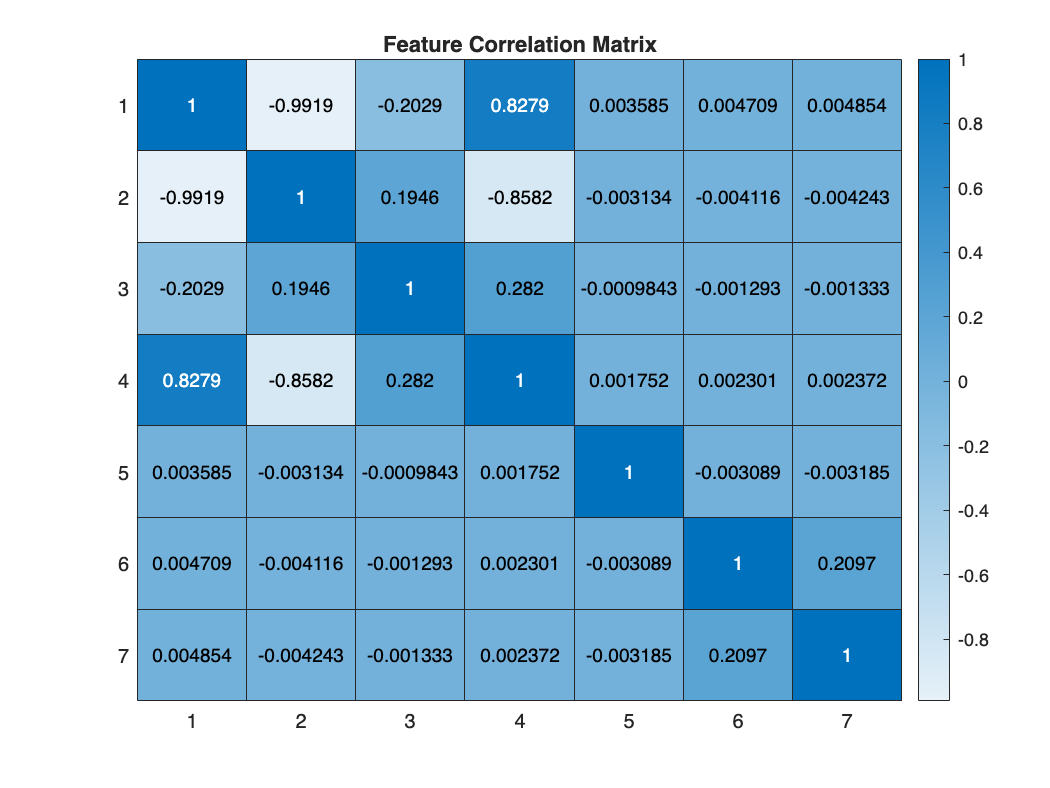

R = corrcoef(X_reduced(2:end,2:end));

figure()
heatmap(R);
title('Feature Correlation Matrix');


[~, p] = size(Xz_reduced(2:end,2:end));

[U,S,V] = svd(Xz_reduced(2:end,2:end), 'econ');
singularValues = diag(S);

dependency = V(:,end);

disp(table((1:p)', dependency, ...
    'VariableNames', {'Feature','Coefficient'}));

    Feature    Coefficient
    _______    ___________
       1          -0.5518 
       2         -0.78725 
       3          0.11243 
       4         -0.25124 
       5       6.2137e-05 
       6       6.6621e-05 
       7       6.9809e-05 



disp('Feature 2 removed')

Feature 2 removed


X_reduced2 = X_reduced;
X_reduced2(:,3) = [];

Xz_reduced2 = zscore(X_reduced2);

beta = (X_reduced2' * X_reduced2) \ X_reduced2' * y;

RMSE = sqrt(1/length(y) * sum((y - X_reduced2 * beta).^2))

RMSE = 2.9688

Removing another feature, in this case the highest correlation one, worsens the fit, as the model is now underfitting when compared to the previous one. However, this process that has been done manually of removing features to improve the model, motivates the search for methods that not only minimize the quadratic error, but rather penalize complex models that do not significantly improve estimations, methods such as Ridge or LASSO.